Raúl Correa Ocañas

A01722401

30 de mayo de 2023

clc
clear all

table = readtable("datos.xlsx")

table = 24×2 table
    i      yi  
    __    _____

     1    6.395
     2    6.435
     3    6.485
     4    6.495
     5    6.505
     6    6.515
     7    6.555
     8    6.555
     9    6.565
    10    6.575
    11    6.595
    12    6.605
    13    6.615
    14    6.625
    15    6.625
    16    6.635


x = table.i;
y = table.yi;

mu = mean(y)

mu = 6.5996

sigma = std(y) % n-1

sigma = 0.0969

sigsq = var(y) % n-1

sigsq = 0.0094

coefvar = sigma./y * 100

coefvar =     1.5147
    1.5053
    1.4936
    1.4913
    1.4891
    1.4868
    1.4777
    1.4777
    1.4754
    1.4732



n = 24;

a1 = (n*sum(x.*y)-sum(x)*sum(y)) / (n*sum(x.^2) - (sum(x)^2))

a1 = 0.0134

a0 = mean(y)-a1*mean(x)

a0 = 6.4315

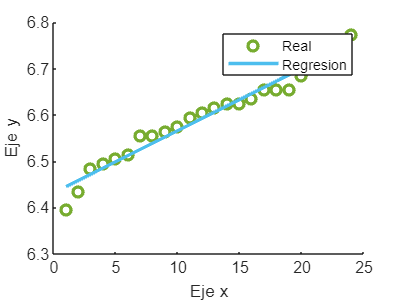


reg = @(x) a1*x + a0;

figure(1)
hold on
index1 = scatter(x,y,"LineWidth",2,"Marker","O");
index2 = plot(x,reg(x),"LineWidth",2);

legend([index1,index2], "Real", "Regresion");
xlabel("Eje x")
ylabel("Eje y")